duration_params = readtable("./output/duration_distributions/allrisk_base_mu_sigma_samples.csv");
intensity_params = readtable("./output/severity_distributions/allrisk_base_mevd_samples.csv");
intensity_params_mle = readtable("./output/severity_distributions/allrisk_base_mevd_mle.csv");

draws = unifrnd(0, 1, [height(duration_params), 200]);

Start by testing duration sampler.

duration_sampler = DurationSampler(duration_params, 10);

durations = duration_sampler.get_duration(draws);

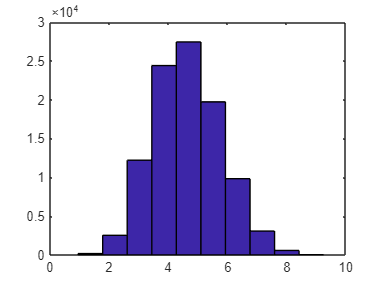

histogram(mean(durations, 2));

This looks like it's working. Let's test the intensity sampler next.

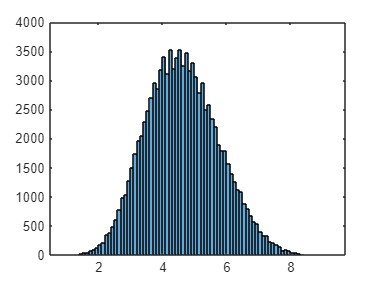

intensity_sampler = ParametrizedSeveritySampler(intensity_params, 0.01, 57);

intensity_sampler_mle = ParametrizedSeveritySampler(intensity_params_mle, 0.01, 57);

intensity_samples = intensity_sampler.get_severity(draws);
histogram(mean(intensity_samples, 2), 'Normalization', 'countdensity');

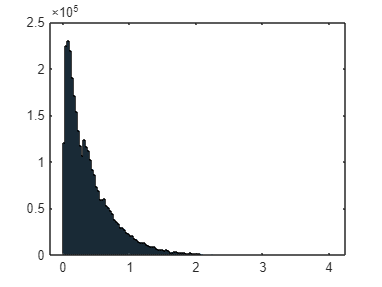

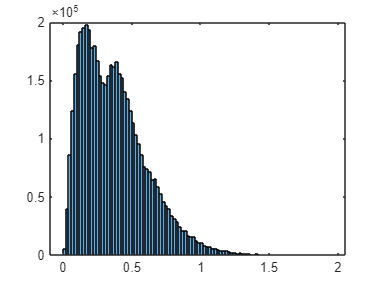

intensity_samples_mle = intensity_sampler_mle.get_severity(draws);
histogram(mean(intensity_samples_mle, 2), 'Normalization', 'countdensity');

You can calculate moments for some of these to check but I think I buy that this is correct.